# Lab1

## Part1

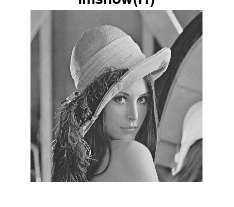

I1=imread("lena_gray.bmp"); %file type uint8. image size 512*512
%3
imtool(I1);title("imtool(I1)");
%4
imshow(I1);title("imshow(I1)");

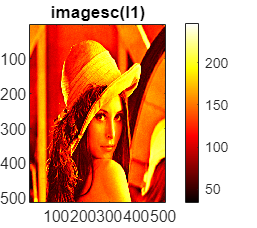

%5
imagesc(I1);title("imagesc(I1)");
colormap("gray");
colorbar;
%6
colormap(hot);
colorbar;

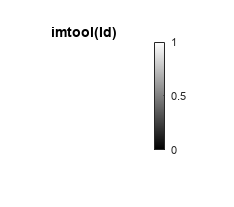

%7
Id=double(I1); 
%8.4
imshow(Id); title("imtool(Id)");
colorbar;

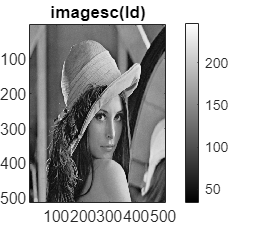

%8.5
imagesc(Id); title("imagesc(Id)");
colormap("gray");
colorbar;

## Part2

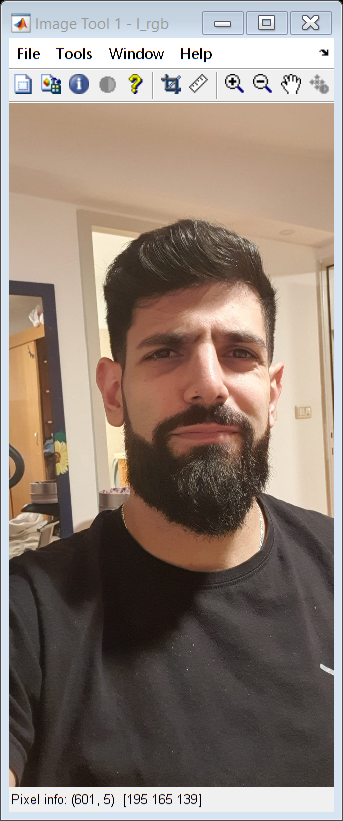

%a
I_rgb=imread("ben.jpg");
s=size(I_rgb);
%b
imtool(I_rgb);

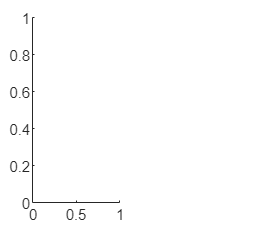

Unrecognized function or variable 'a'.

%d
rect= [224 316 607 1006];
I2= imcrop(I_rgb,rect);
%e
imresize(I2,2,"bilinear");
%f
I=rgb2gray(I2);
imwrite(I,"head.jpg");
%g
maxHead=max(I(:));
minHead=min(I(:));
%h DO AT HOME
[r,c]=size(I);
for row_H_first=1:1:r
    k=1;
    for j=c:-1:1
        temp=I(row_H_first,k);
        result(row_H_first,k)=I(row_H_first,j);
        result(row_H_first,j)=temp;
        k=k+1;
    end
end
subplot(1,2,1),imshow(a), subplot(1,2,2),imshow(result);

## Part3

%1
close all;
h=fspecial('disk',20);
%a
whos h;
%b
hmin = min(h(:));
hmax=max(h(:));
%c ?
h1=h./hmax;
whos h1;
%d
h1_padded = padarray(h1,[40 10],"both");
whos h1_padded;
%e
figure(1)
subplot(2,1,1);
imshow(h1);
colorbar;
subplot(2,1,2);
imshow(h1_padded);
colorbar;
%f
row_H_first=1;
while(h1_padded(row_H_first,:)==0)
    row_H_first=row_H_first+1;
end
row_H_last=121;
while(h1_padded(row_H_last,:)==0)
    row_H_last=row_H_last-1;
end
%g
col_H_first=1;
while(h1_padded(:,col_H_first)==0)
    col_H_first=col_H_first+1;
end
col_H_last=61;
while(h1_padded(:,col_H_last)==0)
    col_H_last=col_H_last-1;
end
%h??


## Part4

%2
h=fspecial('gaussian',[100,100],10);
%3 varible type is double. 
Size=size(h);%size is 100x100.
%a
minNum=min(h(:));%min is 3.6351e-14
maxNum=max(h(:));%max is 0.0016
%b
surf(h);
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('gaussian in 3D')%%%needs title and axes names
%c


